clf;
clear;

circuitA = imread("../images/circuitboard-a.tif");
circuitB = imread("../images/circuitboard-b.tif");
circuitC = imread("../images/circuitboard-c.tif");
circuitD = imread("../images/circuitboard-d.tif");
[M,N] = size(circuitA)

M = 448

N = 464

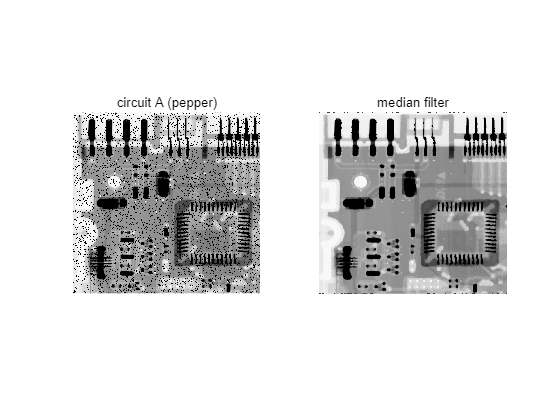

% imshow(circuitA);
% imshow(circuitB);
% imshow(circuitC);
% imshow(circuitD);

A = my_median_filter(circuitA, 5);
A = uint8(A);
subplot(1,2,1);
imshow(circuitA);title('circuit A (pepper)');
subplot(1,2,2);
imshow(A);title('median filter');

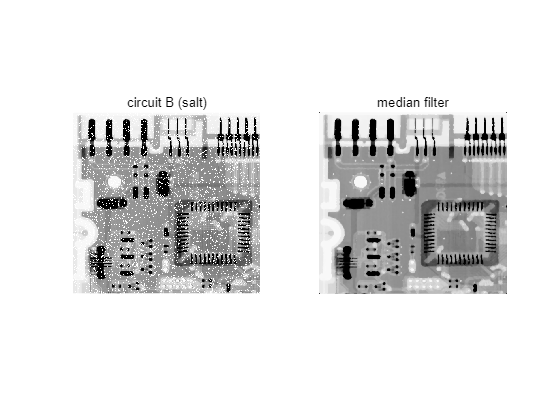


figure;
B = my_median_filter(circuitB, 5);
B = uint8(B);
subplot(1,2,1);
imshow(circuitB);title('circuit B (salt)');
subplot(1,2,2);
imshow(B);title('median filter');

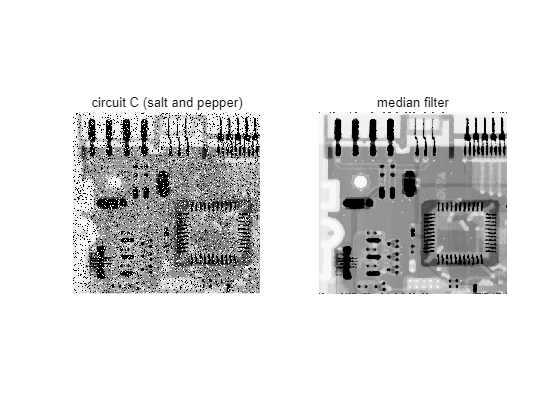


figure;
C = my_median_filter(circuitC, 5);
C = uint8(C);
subplot(1,2,1);
imshow(circuitC);title('circuit C (salt and pepper)');
subplot(1,2,2);
imshow(C);title('median filter');

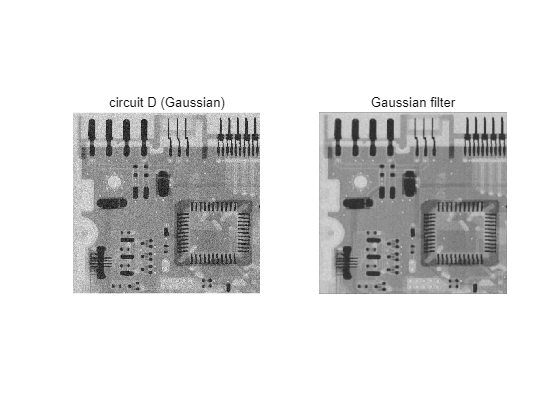


figure;
% D = my_median_filter(circuitD, 3);
G = Gaussian([5 5],1);
D = my_corr_same(circuitD,G);
D = uint8(D);
subplot(1,2,1);
imshow(circuitD);title('circuit D (Gaussian)');
subplot(1,2,2);
imshow(D);title('Gaussian filter');

function output=my_median_filter(I,kernal)
[M,N] = size(I);
output = ones(M,N);
I_tmp = zeros(M+kernal-1,N+kernal-1);
I_tmp(1+(kernal-1)/2:M+(kernal-1)/2,1+(kernal-1)/2:N+(kernal-1)/2) = I;

for i = 1:M
    for j = 1:N
        tmp = I_tmp(i:(i+kernal-1), j:(j+kernal-1));
        tmp = tmp(:);
        output(i,j) = med_sort(tmp);
    end
end
end

%=========================
% bubble sort
function medvalue=med_sort(buff)
V = length(buff);

for m=1:V-1
    for n=1:V-1
        if buff(n)>buff(n+1)
        temp = buff(n);
        buff(n) = buff(n+1);
        buff(n+1) = temp ;
        end
    end
end
medvalue = buff((V+1)/2);
end

%=========================
% Gaussian Filter
function output = Gaussian(hsize, sigma)
hhsize = (hsize-1)/2;
[x,y] = meshgrid(-hhsize(2):hhsize(2),-hhsize(1):hhsize(1));
output = exp(-(x.*x + y.*y)/(2*sigma*sigma));

cum = sum(output(:));
output = output/cum;
end

%=========================
% corr_same
function result = my_corr_same(img, kernal)
[M,N] = size(img);
[k,kk] = size(kernal);
img_tmp = zeros(M+k-1,N+k-1);
result = zeros(M,N);

img_tmp(1+(k-1)/2:M+(k-1)/2,1+(k-1)/2:N+(k-1)/2) = img;

for i = 1:M
    for j = 1:N
        tmp = kernal.*img_tmp(i:i+k-1,j:j+kk-1);
        tmp = sum(tmp(:));
        result(i,j) = tmp;
    end
end
end